clear all;   % This clears all workspaces
close all;   % This closes all figures 
clc;         % This clears the command window
format long; 

name = 'Neo Lee';
id = 'A17050803';
hw_num = 7;

%% Problem 1
% (a - d)
i = 0;
load terrain.mat
[n, m] = size(altitude)

n =    201

m =    161

for a = 2:n-1
    for b = 2:m-1
        compare_element = altitude(a-1:a+1, b-1:b+1);
        if altitude(a, b) >= max(compare_element(:))
            i = i + 1;
            peakx(i) = x(a);
            peaky(i) = y(b);
            peak_altitude(i) = altitude(a,b);
        end
    end
end
p1a = i

p1a =      6

p1b = peakx

p1b =       -42000      -21000      -21000        2000       32000       32000


p1c = peaky

p1c =            0      -23000       23000           0      -30000       30000


p1d = peak_altitude

p1d = 1.0e+03 *

   0.973250000000000   1.178775000000000   1.178775000000000   1.570200000000000   0.802775000000000   0.802775000000000



% (e - g)
[a, b] = find(altitude > 1100);
p1e = x(a)

p1e =       -23000      -22500      -22000      -21500      -21000      -20500      -20000      -19500      -24000      -23500      -23000      -22500      -22000      -21500      -21000      -20500      -20000      -19500      -19000      -18500      -24500      -24000      -23500      -23000      -22500      -22000      -21500      -21000      -20500      -20000      -19500      -19000      -18500      -18000      -17500      -25500      -25000      -24500      -24000      -23500      -23000      -22500      -22000      -21500      -21000      -20500      -20000      -19500      -19000      -18500


p1f = y(b)

p1f =       -29500      -29500      -29500      -29500      -29500      -29500      -29500      -29500      -29000      -29000      -29000      -29000      -29000      -29000      -29000      -29000      -29000      -29000      -29000      -29000      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28500      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000      -28000


p1g = altitude(altitude > 1100)'

p1g = 1.0e+03 *

   1.100175000000000   1.102850000000000   1.104800000000000   1.105975000000000   1.106325000000000   1.105850000000000   1.104500000000000   1.102250000000000   1.101700000000000   1.105850000000000   1.109325000000000   1.112100000000000   1.114100000000000   1.115325000000000   1.115675000000000   1.115175000000000   1.113800000000000   1.111475000000000   1.108200000000000   1.103950000000000   1.105300000000000   1.110225000000000   1.114475000000000   1.118050000000000   1.120900000000000   1.122950000000000   1.124200000000000   1.124575000000000   1.124075000000000   1.122650000000000   1.120250000000000   1.116900000000000   1.112550000000000   1.107200000000000   1.100800000000000   1.101425000000000   1.107625000000000   1.113275000000000   1.118300000000000   1.122675000000000   1.126325000000000   1.129225000000000   1.131325000000000   1.132625000000000   1.133000000000000   1.132475000000000   1.131025000000000   1.128575000000000   1.125125000000000   


% for extra credit (i)
n = find(x == 8000)

n =    117

m = find(y == -8000)

m =     65

i = 1;
compare_element = altitude(n-1:n+1, m-1:m+1)

compare_element = 1.0e+03 *

   1.093825000000000   1.125675000000000   1.156550000000000
   1.073625000000000   1.104575000000000   1.134575000000000
   1.052350000000000   1.082350000000000   1.111400000000000


altitude_track(1) = altitude(n, m)

altitude_track =      1.104575000000000e+03

trackx(1) = x(n)

trackx =         8000

tracky(1) = y(m)

tracky =        -8000

while altitude(n, m) > min(compare_element(:))
    i = i+1;
    [a, b] = find(compare_element == min(compare_element(:)))
    n = n + a - 2
    m = m + b - 2
    altitude_track(i) = min(compare_element(:))
    trackx(i) = x(n)
    tracky(i) = y(m)
    compare_element = altitude(n-1:n+1, m-1:m+1)
end

a =      3

b =      1

n =    118

m =     64

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000


trackx =         8000        8500


tracky =        -8000       -8500


compare_element = 1.0e+03 *

   1.041850000000000   1.073625000000000   1.104575000000000
   1.021600000000000   1.052350000000000   1.082350000000000
   1.000500000000000   1.030175000000000   1.059075000000000


a =      3

b =      1

n =    119

m =     63

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000


trackx =         8000        8500        9000


tracky =        -8000       -8500       -9000


compare_element = 1.0e+03 *

   0.990225000000000   1.021600000000000   1.052350000000000
   0.970200000000000   1.000500000000000   1.030175000000000
   0.949550000000000   0.978625000000000   1.007125000000000


a =      3

b =      1

n =    120

m =     62

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000


trackx =         8000        8500        9000        9500


tracky =        -8000       -8500       -9000       -9500


compare_element = 1.0e+03 *

   0.939500000000000   0.970200000000000   1.000500000000000
   0.920050000000000   0.949550000000000   0.978625000000000
   0.900100000000000   0.928300000000000   0.956075000000000


a =      3

b =      1

n =    121

m =     61

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000


trackx =         8000        8500        9000        9500       10000


tracky =        -8000       -8500       -9000       -9500      -10000


compare_element = 1.0e+02 *

   8.902999999999999   9.200500000000000   9.495500000000000
   8.716500000000002   9.000999999999999   9.282999999999999
   8.526500000000000   8.796749999999999   9.065000000000000


a =      3

b =      1

n =    122

m =     60

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000


trackx =         8000        8500        9000        9500       10000       10500


tracky =        -8000       -8500       -9000       -9500      -10000      -10500


compare_element = 1.0e+02 *

   8.430750000000000   8.716500000000002   9.000999999999999
   8.254750000000000   8.526500000000000   8.796749999999999
   8.076250000000000   8.333250000000000   8.589000000000000


a =      3

b =      1

n =    123

m =     59

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000


trackx =         8000        8500        9000        9500       10000       10500       11000


tracky =        -8000       -8500       -9000       -9500      -10000      -10500      -11000


compare_element = 1.0e+02 *

   7.983000000000001   8.254750000000000   8.526500000000000
   7.819500000000001   8.076250000000000   8.333250000000000
   7.654750000000000   7.896250000000000   8.138000000000000


a =      3

b =      1

n =    124

m =     58

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000


trackx =         8000        8500        9000        9500       10000       10500       11000       11500


tracky =        -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500


compare_element = 1.0e+02 *

   7.564249999999999   7.819500000000001   8.076250000000000
   7.415000000000000   7.654750000000000   7.896250000000000
   7.265750000000000   7.489750000000000   7.715250000000000


a =      3

b =      1

n =    125

m =     57

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000


trackx =         8000        8500        9000        9500       10000       10500       11000       11500       12000


tracky =        -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000


compare_element = 1.0e+02 *

   7.177750000000000   7.415000000000000   7.654750000000000
   7.044000000000000   7.265750000000000   7.489750000000000
   6.911500000000000   7.117000000000001   7.324500000000000


a =      3

b =      1

n =    126

m =     56

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000


trackx =         8000        8500        9000        9500       10000       10500       11000       11500       12000       12500


tracky =        -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500


compare_element = 1.0e+02 *

   6.826250000000000   7.044000000000000   7.265750000000000
   6.709749999999999   6.911500000000000   7.117000000000001
   6.595250000000000   6.780750000000000   6.969500000000000


a =      3

b =      1

n =    127

m =     55

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000


trackx =         8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000


tracky =        -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000


compare_element = 1.0e+02 *

   6.512250000000000   6.709749999999999   6.911500000000000
   6.413750000000000   6.595250000000000   6.780750000000000
   6.317500000000000   6.482500000000000   6.651500000000000


a =      3

b =      1

n =    128

m =     54

altitude_track = 1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000


trackx =         8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500


tracky =        -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500


compare_element = 3×3
   6.237250000000000   6.413750000000000   6.595250000000000
   6.157250000000000   6.317500000000000   6.482500000000000
   6.080000000000000   6.224000000000000   6.372250000000000


a =      3

b =      1

n =    129

m =     53

altitude_track = 1×13
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000


trackx = 1×13
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000


tracky = 1×13
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000


compare_element = 3×3
   6.002250000000000   6.157250000000000   6.317500000000000
   5.941000000000000   6.080000000000000   6.224000000000000
   5.882750000000000   6.005750000000001   6.133250000000000


a =      3

b =      1

n =    130

m =     52

altitude_track = 1×14
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000


trackx = 1×14
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500


tracky = 1×14
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500


compare_element = 3×3
   5.807500000000000   5.941000000000000   6.080000000000000
   5.765000000000000   5.882750000000000   6.005750000000001
   5.725499999999999   5.827750000000000   5.934750000000000


a =      3

b =      1

n =    131

m =     51

altitude_track = 1×15
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000


trackx = 1×15
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000


tracky = 1×15
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000


compare_element = 3×3
   5.653000000000000   5.765000000000000   5.882750000000000
   5.628500000000000   5.725499999999999   5.827750000000000
   5.607500000000000   5.689000000000000   5.775750000000000


a =      3

b =      1

n =    132

m =     50

altitude_track = 1×16
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000


trackx = 1×16
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500


tracky = 1×16
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500


compare_element = 3×3
   5.537250000000000   5.628500000000000   5.725499999999999
   5.530750000000000   5.607500000000000   5.689000000000000
   5.526750000000000   5.589250000000001   5.656000000000001


a =      3

b =      1

n =    133

m =     49

altitude_track = 1×17
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000


trackx = 1×17
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000


tracky = 1×17
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000


compare_element = 3×3
   5.459250000000001   5.530750000000000   5.607500000000000
   5.469500000000000   5.526750000000000   5.589250000000001
   5.482500000000000   5.526000000000000   5.574000000000000


a =      1

b =      1

n =    132

m =     48

altitude_track = 1×18
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000


trackx = 1×18
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500


tracky = 1×18
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500


compare_element = 3×3
   5.373250000000000   5.452000000000001   5.537250000000000
   5.393750000000000   5.459250000000001   5.530750000000000
   5.417250000000000   5.469500000000000   5.526750000000000


a =      1

b =      1

n =    131

m =     47

altitude_track = 1×19
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000


trackx = 1×19
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000


tracky = 1×19
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000


compare_element = 3×3
   5.270250000000000   5.355250000000000   5.447750000000000
   5.300750000000001   5.373250000000000   5.452000000000001
   5.334250000000000   5.393750000000000   5.459250000000001


a =      1

b =      1

n =    130

m =     46

altitude_track = 1×20
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000


trackx = 1×20
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500


tracky = 1×20
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500


compare_element = 3×3
   5.153250000000001   5.242999999999999   5.340500000000000
   5.192750000000000   5.270250000000000   5.355250000000000
   5.235499999999999   5.300750000000001   5.373250000000000


a =      1

b =      1

n =    129

m =     45

altitude_track = 1×21
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000


trackx = 1×21
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000


tracky = 1×21
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000


compare_element = 3×3
   5.025000000000000   5.117249999999999   5.218750000000000
   5.072249999999999   5.153250000000001   5.242999999999999
   5.123250000000001   5.192750000000000   5.270250000000000


a =      1

b =      1

n =    128

m =     44

altitude_track = 1×22
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000


trackx = 1×22
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500


tracky = 1×22
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500


compare_element = 3×3
   4.888500000000000   4.981750000000000   5.085250000000000
   4.942250000000000   5.025000000000000   5.117249999999999
   5.000000000000000   5.072249999999999   5.153250000000001


a =      1

b =      1

n =    127

m =     43

altitude_track = 1×23
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000


trackx = 1×23
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000


tracky = 1×23
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000


compare_element = 3×3
   4.746500000000000   4.839000000000000   4.943000000000000
   4.805499999999999   4.888500000000000   4.981750000000000
   4.869000000000000   4.942250000000000   5.025000000000000


a =      1

b =      1

n =    126

m =     42

altitude_track = 1×24
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000


trackx = 1×24
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500


tracky = 1×24
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500


compare_element = 3×3
   4.602749999999999   4.692750000000000   4.794500000000000
   4.665249999999999   4.746500000000000   4.839000000000000
   4.733250000000000   4.805499999999999   4.888500000000000


a =      1

b =      1

n =    125

m =     41

altitude_track = 1×25
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000


trackx = 1×25
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000


tracky = 1×25
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000


compare_element = 3×3
   4.460000000000000   4.545750000000000   4.644500000000001
   4.524750000000000   4.602749999999999   4.692750000000000
   4.595500000000000   4.665249999999999   4.746500000000000


a =      1

b =      1

n =    124

m =     40

altitude_track = 1×26
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000


trackx = 1×26
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500


tracky = 1×26
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500


compare_element = 3×3
   4.321750000000000   4.401500000000000   4.495000000000000
   4.387000000000000   4.460000000000000   4.545750000000000
   4.459000000000000   4.524750000000000   4.602749999999999


a =      1

b =      1

n =    123

m =     39

altitude_track = 1×27
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000


trackx = 1×27
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000


tracky = 1×27
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000


compare_element = 3×3
   4.190750000000000   4.263250000000000   4.350000000000000
   4.255250000000000   4.321750000000000   4.401500000000000
   4.327000000000000   4.387000000000000   4.460000000000000


a =      1

b =      1

n =    122

m =     38

altitude_track = 1×28
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000


trackx = 1×28
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500


tracky = 1×28
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500


compare_element = 3×3
   4.070750000000000   4.134500000000000   4.213000000000000
   4.132500000000000   4.190750000000000   4.263250000000000
   4.202500000000000   4.255250000000000   4.321750000000000


a =      1

b =      1

n =    121

m =     37

altitude_track = 1×29
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000


trackx = 1×29
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000


tracky = 1×29
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000


compare_element = 3×3
   3.963500000000000   4.017500000000000   4.086250000000000
   4.021500000000000   4.070750000000000   4.134500000000000
   4.087750000000000   4.132500000000000   4.190750000000000


a =      1

b =      1

n =    120

m =     36

altitude_track = 1×30
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×30
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×30
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.872250000000000   3.915000000000000   3.973250000000000
   3.924750000000000   3.963500000000000   4.017500000000000
   3.986500000000000   4.021500000000000   4.070750000000000


a =      1

b =      1

n =    119

m =     35

altitude_track = 1×31
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×31
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×31
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.799000000000000   3.830000000000000   3.876500000000000
   3.844500000000000   3.872250000000000   3.915000000000000
   3.900250000000000   3.924750000000000   3.963500000000000


a =      1

b =      1

n =    118

m =     34

altitude_track = 1×32
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×32
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×32
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.745250000000000   3.764000000000000   3.798000000000000
   3.782999999999999   3.799000000000000   3.830000000000000
   3.831250000000000   3.844500000000000   3.872250000000000


a =      1

b =      1

n =    117

m =     33

altitude_track = 1×33
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×33
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×33
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.713250000000000   3.718750000000000   3.740250000000000
   3.741750000000000   3.745250000000000   3.764000000000000
   3.781500000000000   3.782999999999999   3.799000000000000


a =      1

b =      1

n =    116

m =     32

altitude_track = 1×34
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×34
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×34
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.703250000000000   3.696000000000000   3.704000000000000
   3.722000000000000   3.713250000000000   3.718750000000000
   3.752500000000000   3.741750000000000   3.745250000000000


a =      1

b =      2

n =    115

m =     32

altitude_track = 1×35
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×35
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×35
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.696250000000000   3.691000000000000   3.701000000000000
   3.703250000000000   3.696000000000000   3.704000000000000
   3.722000000000000   3.713250000000000   3.718750000000000


a =      1

b =      2

n =    114

m =     32

altitude_track = 1×36
1.0e+03 *

   1.104575000000000   1.052350000000000   1.000500000000000   0.949550000000000   0.900100000000000   0.852650000000000   0.807625000000000   0.765475000000000   0.726575000000000   0.691150000000000   0.659525000000000   0.631750000000000   0.608000000000000   0.588275000000000   0.572550000000000   0.560750000000000   0.552675000000000   0.545925000000000   0.537325000000000   0.527025000000000   0.515325000000000   0.502500000000000   0.488850000000000   0.474650000000000   0.460275000000000   0.446000000000000   0.432175000000000   0.419075000000000   0.407075000000000   0.396350000000000


trackx = 1×36
        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       15500       15000       14500       14000       13500       13000       12500       12000       11500       11000       10500       10000        9500


tracky = 1×36
       -8000       -8500       -9000       -9500      -10000      -10500      -11000      -11500      -12000      -12500      -13000      -13500      -14000      -14500      -15000      -15500      -16000      -16500      -17000      -17500      -18000      -18500      -19000      -19500      -20000      -20500      -21000      -21500      -22000      -22500


compare_element = 3×3
   3.701750000000000   3.698000000000000   3.710000000000000
   3.696250000000000   3.691000000000000   3.701000000000000
   3.703250000000000   3.696000000000000   3.704000000000000


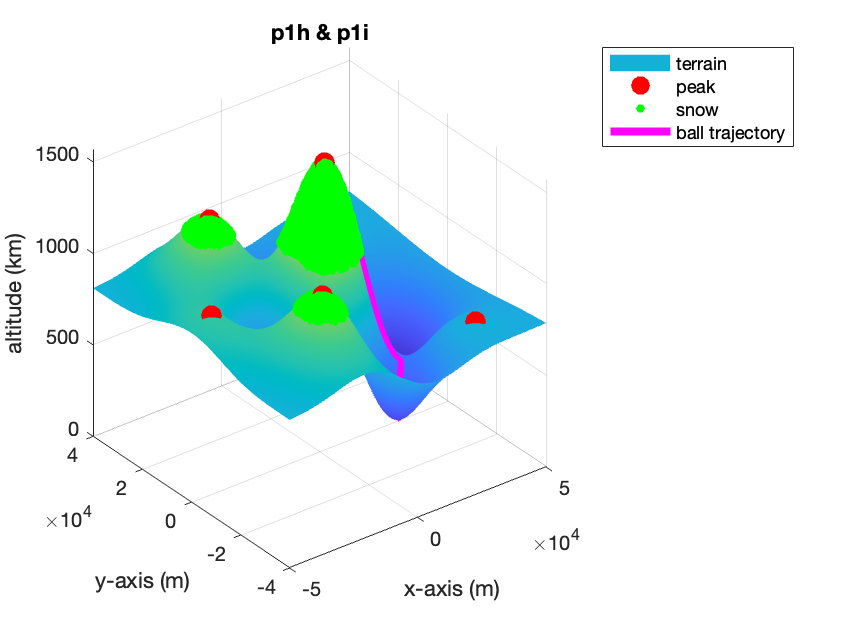


% plot graph for (h) & (i)
figure(1)
hold on
grid on
surf(x, y, altitude')
shading interp
plot3(peakx, peaky, peak_altitude, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r')
plot3(p1e, p1f, p1g, 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'g')
plot3(trackx, tracky, altitude_track, '-m', 'LineWidth', 4)
view(3)
xlabel('x-axis (m)')
ylabel('y-axis (m)')
zlabel('altitude (km)')
title('p1h & p1i')
legend('terrain', 'peak', 'snow', 'ball trajectory')

p1h = 'See figure 1'

p1h = 'See figure 1'

p1i = 'See ball trajectory'

p1i = 'See ball trajectory'


%% Problem 2
load matB.mat
% (a)
[n, m] = size(matB)

n =     15

m =     15

element_sum = 0;
for b = 2:m
    for a = 1:n
        if a == b
            break
        end
        element_sum = element_sum + matB(a,b);
    end
end
p2a = element_sum

p2a =         1053


% (b)
element_product = 1;
for a = 2:n
    for b = 1:m
        if a == b
            break
        end
        element_product = element_product*matB(a, b);
    end
end
p2b = element_product

p2b =      8.961249757777589e+96


% (c)
element_sum = 0;
for a = 1:n
    for b = 1:m
        if b == 2*a
            continue
        end
        element_sum = element_sum + matB(a, b);
    end
end
p2c = element_sum

p2c =         2273


% (d)
element_product = 1;
for a = 1:n
    for b = 1:m
        if matB(a, b) > a
            continue
        end
        element_product = element_product*matB(a, b);
    end
end
p2d = element_product

p2d =      8.160318885370118e+66


%% Problem 3
% (a)
p3a = evalc('help car')

p3a =     '  This function solves for the motion of the car
       Call function with format [T, X, U] = car(Tf, dt)
       T is time, X is distance, U is velocity of the car
       Tf is total traveling time, dt is time step
     
     '


% (b - d)
[p3b, p3c, p3d] = car(60, 10)

p3b = 1×7
     0    10    20    30    40    50    60


p3c = 1×7
1.0e+03 *

                   0                   0                   0   0.181715495345897   0.523355992804100   0.946779639584190   1.404257958221058


p3d = 1×7
                   0                   0  18.171549534589687  34.164049745820307  42.342364678009005  45.747831863686834  47.059645416951348



% (e - g)
[p3e, p3f, p3g] = car(60, 1)

p3e = 1×61
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


p3f = 1×61
                   0                   0                   0   0.000249168434429   0.000991726477631   0.002462208199945   0.004881120754823   0.008451169206747   0.013354172354175   0.019748751270409   0.027768825530828   0.037522907296172   0.049094144014976   0.062541028967415   0.077898676566269   0.095180546548421   0.114380497305802   0.135475052318879   0.158425773271867   0.183181647111117   0.209681410294135   0.237855750227968   0.267629340182924   0.298922678900661   0.331653719129405   0.365739280130997   0.401096247757935   0.437642572101781   0.475298077183503   0.513985099967370


p3g = 1×61
                   0                   0   0.249168434429357   0.742558043202020   1.470481722313545   2.418912554877716   3.570048451924131   4.903003147427767   6.394578916234604   8.020074260418923   9.754081765344360  11.571236718803329  13.446884952439607  15.357647598854101  17.281869982151470  19.199950757381263  21.094555013076317  22.950720952988664  24.755873839250089  26.499763183017521  28.174339933833004  29.773589954956066  31.293338717736805  32.731040228743957  34.085561001592197  35.356967626937880  36.546324343846564  37.655505081722133  38.687022783866098  39.643877463172252


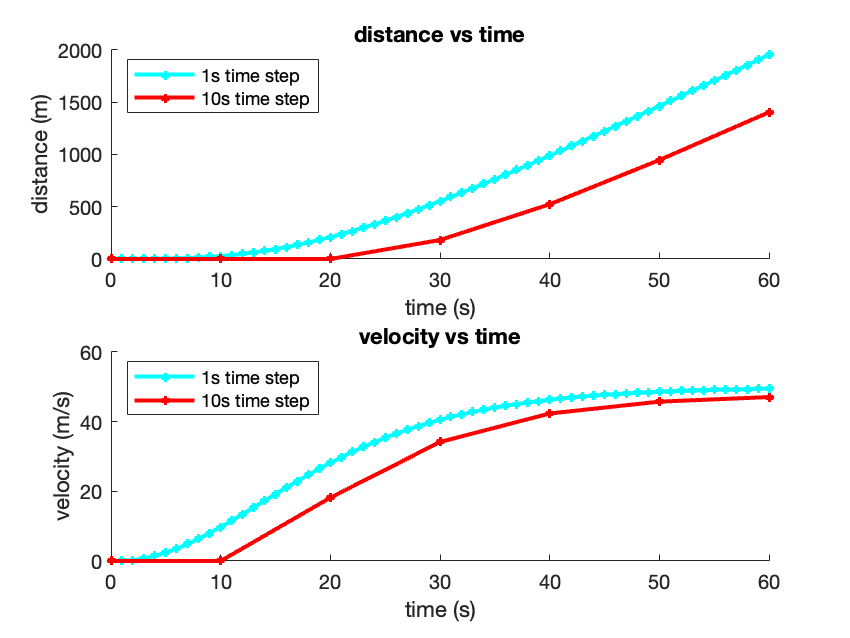


% (h)
figure(2)
subplot(2,1,1)
hold on
plot(p3e, p3f, '-co', 'LineWidth', 2, 'MarkerFaceColor', 'c', 'MarkerSize', 3)
plot(p3b, p3c, '-ro', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 3)
xlabel('time (s)')
ylabel('distance (m)')
title('distance vs time')
legend('1s time step', '10s time step', 'Location','northwest')

subplot(2,1,2)
hold on
plot(p3e, p3g, '-co', 'LineWidth', 2, 'MarkerFaceColor', 'c', 'MarkerSize', 3)
plot(p3b, p3d, '-ro', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 3)
xlabel('time (s)')
ylabel('velocity (m/s)')
title('velocity vs time')
legend('1s time step', '10s time step', 'Location','northwest')


p3h = 'See figure 2'

p3h = 'See figure 2'


%% Problem 4
p4a = evalc('help rocket')

p4a =     '  This functions solves for the motion of the rocket
       Call function with format [T, Z, W] = rocket(Tf, dt)
       T is time, Z is altitude, W is velocity
       Tf is total traveling time, dt is time step
     
     '

p4b = evalc('help gravity')

p4b =     '
     gravity not found.
     
     Use the Help browser search field to search the documentation, or
     type "help help" for help command options, such as help for methods.
     
     '

p4c = evalc('help thrust')

p4c =     '--- thrust not found. Showing help for trust instead. ---
     
     trust is a function.
         [s, val, posdef, count, lambda] = trust(g, H, delta)
     
     '

p4d = evalc('help rocket>gravity')

p4d =     '  This function calculates the gravity force in different altitude
       g = 9.81*(1-(z/10000)^3) for 0 <= z < 10000
       g = 0 for 10000 <= z
       Call format: [g] = gravity(z)
       g is gravity, z is altitude
     
     '

p4e = evalc('help rocket>thrust')

p4e =     '  This function calculates the thrust in different time interval
       Thrust = 670N for 0 <= t < 2
       Thrust = 1360N for 2 <= t < 4
       Thrust = 0N for 4 <= t
       Call format: [Th] = thrust(t)
       Th is thrust, t is time
     
     '

[T, Z, W] = rocket(120, 0.1)

T = 1×1201
                   0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000000   2.000000000000000   2.100000000000000   2.200000000000000   2.300000000000000   2.400000000000000   2.500000000000000   2.600000000000000   2.700000000000000   2.800000000000000   2.900000000000000


Z = 1×1201
                   0   0.000571900000000   0.001715700000000   0.003431400000001   0.005719000000005   0.008578500000028   0.012009900000113   0.016013200000367   0.020588400001025   0.025735500002538   0.031454500005724   0.037745400011963   0.044608200023477   0.052042900043699   0.060049500077749   0.068628000133041   0.077778400220041   0.087500700353199   0.097794900552078   0.108661000842710   0.120099001259202   0.132798901845631   0.146760702661808   0.161984403788083   0.178470005331312   0.196217507432196   0.215226910274188   0.235498214094225   0.257031419195507   0.279826525962606


W = 1×1201
                   0   0.057190000000000   0.114380000000002   0.171570000000051   0.228760000000448   0.285950000002283   0.343140000008476   0.400330000025469   0.457520000065751   0.514710000151363   0.571900000318575   0.629090000623868   0.686280001151415   0.743470002022205   0.800660003404986   0.857850005529195   0.915040008700025   0.972230013315815   1.029420019887906   1.086610029063151   1.143800041649220   1.269990058642890   1.396180081617729   1.522370112627485   1.648560154322930   1.774750210088317   1.900940284199248   2.027130382003722   2.153320510128127   2.279510676709965


p4f = Z(end)

p4f =      6.999413521233139e+03

p4g = W(end)

p4g =     -1.433503267387043e+02

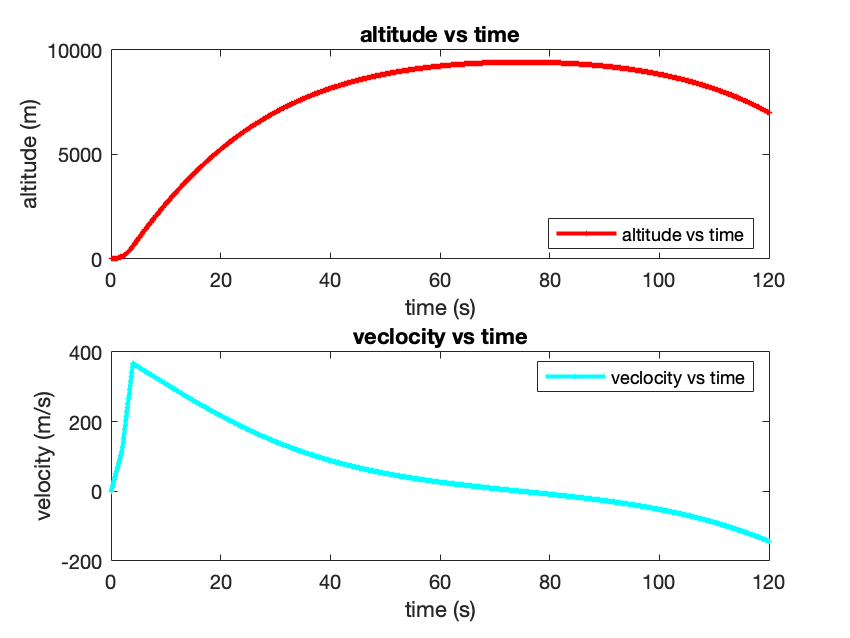


figure(3)
subplot(2,1,1)
plot(T, Z, '-ro', 'LineWidth', 2, 'MarkerSize', 1, 'MarkerFaceColor', 'r')
xlabel('time (s)')
ylabel('altitude (m)')
legend('altitude vs time', 'Location','southeast')
title('altitude vs time')

subplot(2,1,2)
plot(T, W, '-co', 'LineWidth', 2, 'MarkerSize', 1, 'MarkerFaceColor', 'c')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('veclocity vs time', 'Location', 'northeast')
title('veclocity vs time')

p4h = 'See figure 3'

p4h = 'See figure 3'